# Anexo A2-1

Programa de estimação do estado (problema 5-1.4)

clear

% Quantidade de iterações
k = 50;
n = 1;

% Realização
x = zeros(k,n);
u = (zeros(k,n)+1);
f = 1;
g = 1;

% Observação
z = zeros(k,n);
h = 1;

% Definição dos ruídos
rng('default');
r = 1;
q = 0.01;
w = 0 + q.*randn(k,n);
v = 0 + r.*randn(k,n);

% Definição dos estimadores de mínima covariância
p00 = r/h;
P_posteriori = p00;      % P(0|0)

% Condições iniciais
x(1) = 0;
z(1) = v(1);

% Inicialização dos vetores de estimação
x_priori = x;
x_posteriori = x;

% Evolução do estado
for i = 2:k
    % Realização: o estado evolui para x_n
    x(i,:) = (f*x(i-1,:)' + g*u(i-1,:)' + w(i-1,:)')';
    
    % Estimação: estimamos x-_n com base em x+_n-1
    x_priori(i,:) = (f*x_posteriori(i-1,:)'+g*u(i-1,:)')';
    
    % Obtemos P-_n a partir de P+_n-1
    P_priori(i,:) = f*P_posteriori(i-1,:)*f'+q;
    
    % Obtemos K_n a partir de P-_n
    K(i,:) = P_priori(i,:)*h'/(h*P_priori(i,:)*h'+r);
    
    % Obtemos P+_n a partir de P-_n
    P_posteriori(i,:) = (eye(n)-K(i,:)*h)*P_priori(i,:);

    % Observação: medimos z_n
    z(i,:) = (h*x(i,:)' + v(i,:)')';
    
    % Previsão (Filtro de Kalman): estimamos x+_n com base em x-_n, z_n e K_n 
    x_posteriori(i,:) = x_priori(i,:)+(K(i,:)*(z(i,:)'-h*x_priori(i,:)'))';

end

Gera a tabela exibida no Anexo A2-2 com os resultados para a listagem das grandezas pedidas.

resultados(1:k,1) = 1:k;
resultados(1:k,end+1) = x;
resultados(1:k,end+1) = w;
resultados(1:k,end+1) = v;
resultados(1:k,end+1) = z;
resultados(1:k,end+1) = x_priori;
resultados(1:k,end+1) = P_priori;
resultados(1:k,end+1) = h*x_priori;
resultados(1:k,end+1) = h*P_priori*h'+r;
resultados(1:k,end+1) = z-h*x_priori;
resultados(1:k,end+1) = (z-h*x_priori)./((h*P_priori*h+r).^0.5);
resultados(1:k,end+1) = P_priori*h'./(h*P_priori*h'+r);
resultados(1:k,end+1) = x_posteriori;
resultados(1:k,end+1) = P_posteriori;
resultados(1:k,end+1) = x_posteriori./(P_posteriori.^0.5);

Plota os gráficos para visualização do processo de previsão e estimação.

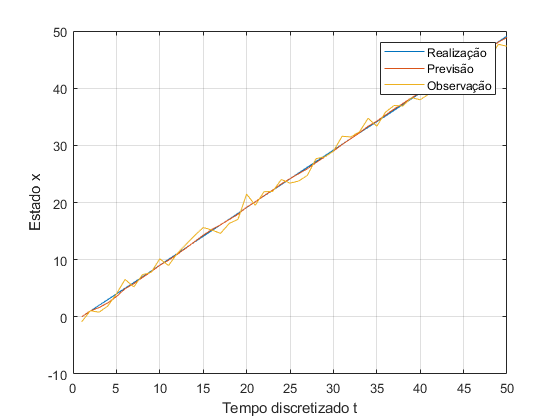

figure;
plot(1:k, x);
hold on;
plot(1:k, x_posteriori);
hold on;
plot(1:k, z);
grid on;
xlabel("Tempo discretizado t");
ylabel("Estado x");
legend("Realização", "Previsão", "Observação");

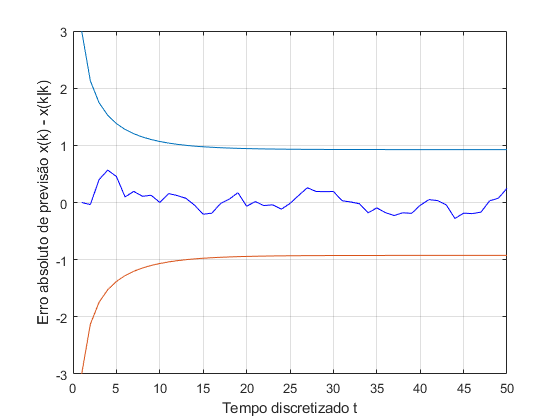


figure
plot(1:k, x-x_posteriori, 'b');
hold on;
grid on;
plot(1:k, 3*sqrt(P_posteriori))
plot(1:k, -3*sqrt(P_posteriori))
xlabel("Tempo discretizado t");
ylabel("Erro absoluto de previsão x(k) - x(k|k)");